# Authors: Marta Barriendos & Ana Garcia Armada, Univesidad Carlos III de Madrid

# SIMULATION OF OFDM WITH MATLAB

## Introduction

Throughout this live script, we will visualize how to implement a basic OFDM channel using Matlab, understanding both theoretical and practical concepts. Subsequently, we will consider a real-world scenario, tailoring the implementation for the case of LTE (4G) and 5G. Finally, we will discuss channel effects and their estimation and compensation for OFDM.

In the next modules, we will talk about the time and frequency synchronization of the OFDM signal. Moreover, we will also delve into more detail on the envelope characteristics of OFDM and PAPR reduction. Finally, we will extend the discussion of OFDM by covering the fundamentals of SC-FDMA.

## Index

- OFDM basics and implementation, frame structure, guards and cyclic prefix.

- LTE (4G) Particularization.

- 5G Particularization.

- Channel effects and their estimation and compesation for OFDM. 

## 1. OFDM BASICS AND IMPLEMENTATION

#### 1.1 What is OFDM?

**Orthogonal Frequency Division Multiplexing** or **OFDM** is a digital, multi-carrier data transmission scheme where a stream of data is split among multiple closely spaced narrowband carrier frequencies or sub-carrier frequencies instead of transmitting the data on a single carrier frequency and over the entire bandwidth. We can see this reflected in the next image, where we have a representation of the different subcarriers that we are going to use during the transmission.

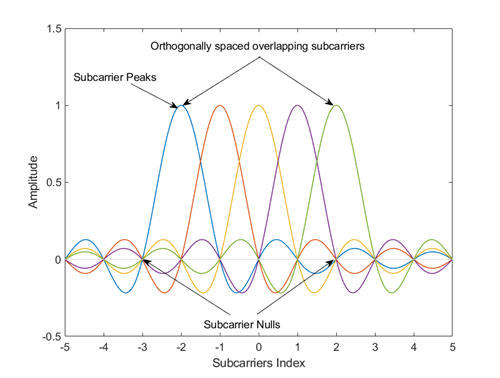

#### 1.2 OFDM Transmission Systems

Once we understand the definition and the concept of OFDM, the next step is to visualize the transmission scheme, where we can see how the main idea is to use the IFFT in the transmission, and the FFT in the reception. Now, we'll dive deeper into this process, to be able to properly implement the desired system.

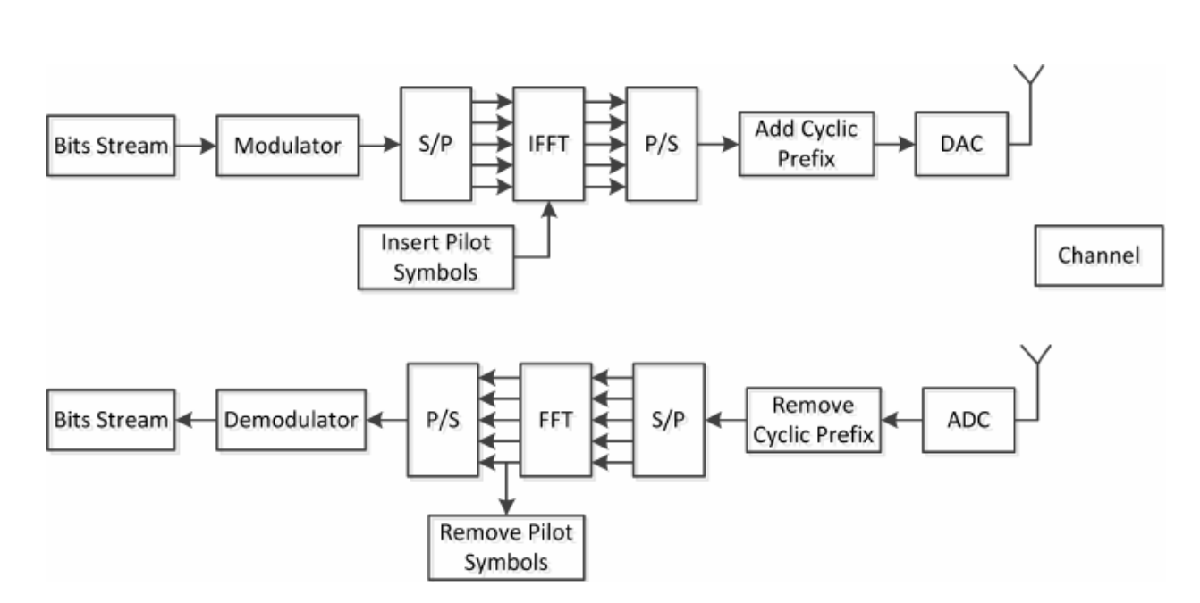

OFDM Systems follow the next equation: 


$$\[
x(t) = \sum_{k=0}^{N-1} X_k e^{j 2\pi \frac{k}{T} t}, \quad 0 \leq t < T
\]$$


Where:

- x(t): Transmitted OFDM signal in the time domain

- Xk: Complex symbol modulating the k-th subcarrier (e.g., from QAM)

- N: Total number of subcarriers

- T: Symbol duration

Thanks to the use of OFDM, we are getting some of the following advantages:

- We are simplifying the problem of channel estimation and equalization (thanks to the N circular convolution):

                
$$

\[
h[n] \overset{N}{*} x[n] \leftrightarrow  H[k] X[k]
\]


$$


- OFDM allows simple mulitplexing schemes for mulitple users. 

- OFDM allows a fine power control in each individual carrier.

#### 1.3 Cyclic prefix

As we have seen before, for the estimation and equalization process we are using the DFT-N, which results in a circular convolution. However, the channel output has the form of a linear convolution:


$$\[
y[n] = h[n] * x[n] = \sum_{\ell=0}^{N-1} h[\ell] \, x[n - \ell]
\]$$


We need to transform this linear convolution in a circular one. In order to do this, the process will be:

- We have the original symbol.

            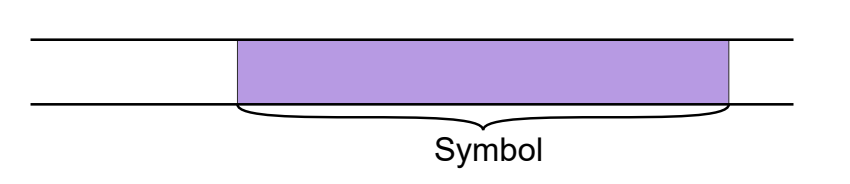

           2. We choose a number of samples for the prefix from the last part of the symbol.

            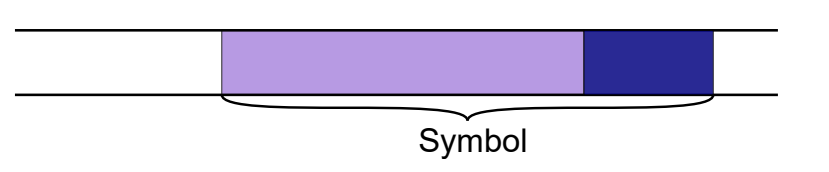

           3. Now we replicate these last samples in the initial part of the symbol, and this will be our cyclic prefix.

            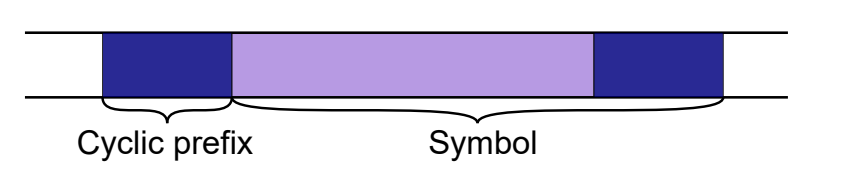

The cyclic prefix (CP) transforms the linear convolution (implicit in the channel model) to a circular convolution. To be effective, the delay spread needs to be shorter than the CP. However, as no data is carried in the CP, it is desirable that it is as short as possible. To conclude, in the implementation below, we have to take in mind, for chosing the length of the CP, that we have a trade off between efficiency and robustness.

#### 1.4 Frame Structure

We already know from the previous section that each OFDM symbol will be composed by different subcarriers, and we'll have some of them set to zero at the beginning and end of the symbol (guard bands), some others will be pilots for the channel estimation, and the rest will be data subcarriers. So our frame will be formed, in each time instant by different subcarriers along which we are going to distribute our data, this representation can be seen in the next image, where we can see the time (*Nt*) of one symbol OFDM, with all the frequencies that it is using**. **

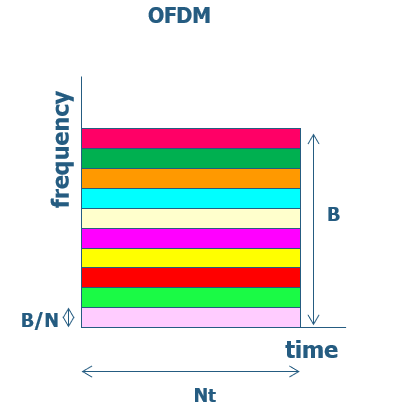

As we have explained before, the last image corresponds to an OFDM symbol with all the frequencies. In a practical case, we would have one OFDM symbol after the other, which results in a grid time-frequency like the one presented below, where each row is a frequency, and therefore a subcarrier, and each column is a time instant that corresponds to one OFDM symbol. 

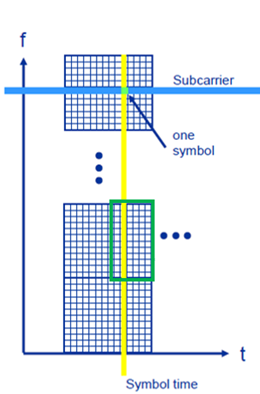

#### 1.5 OFDM Implementation

In this section, we are going to implement an OFDM signal with all the features explained before. 

***1.5.1 Parameter definition***

Let's start discussing the initital parameters we have to define. We have decided for this example to have 2048 subcarriers (*N_OFDM*) for our OFDM symbol. After defining this parameter, we choose for the cyclic prefix a number of carriers equal to $N_g =\frac{1}{8}\times {N\_}_{\textrm{OFDM}}$  (for deciding this, the trade off explained before, should be taken into consideration). Then, for estimating the channel, we need to send a number of known subcarriers in the transmissor, in this case, we decide to have 45 pilots (*num_pilots*) or known subcarriers, with and amplitude of 1 (*P_ampl*). Another relevant paramter that we will use is the Sampling Frequency (*Fs*), that in our case will be 20 MHz. Finally, as last parameters, we define the number of sucarriers that we want to reserve as frecuency guards, that will be placed at the begining and end of the symbol (*fg_1* y *fg_2*). 

N_OFDM=2048;
Ng=1/8*N_OFDM;
num_pilots=45;
P_ampl=1; 
fg_1=171;
fg_2=172;
Fs=20; %MHz

The next step, consists of calculating the number of data or efective subcarriers  (*N_OFDM_ef*) and the number of OFDM symbols that we want to simulate (*N_symb*). Then, with this information, we can calculate the number of real samples in the simulation (*n_samples*).

N_OFDM_ef=N_OFDM-fg_1-fg_2-num_pilots;
N_symb=100; 
n_samples=N_symb.*N_OFDM_ef; 

fprintf('number of subcarriers for frequency guards: %f, %f  1/%f\n',fg_1,fg_2,N_OFDM/Ng);

number of subcarriers for frequency guards: 171.000000, 172.000000  1/8.000000


fprintf('%f pilots with amplitude=%f\n',num_pilots,P_ampl);

45.000000 pilots with amplitude=1.000000


Now we can create the vector of pilots. We start specifying the position for the 45 pilots (*P*). We start calculating the number of subcarriers between a pilot and the next one (*delta*). And then, we can create the vector (*P*) that contains the position of the pilots, and already has space between two consecutive pilots to introduce the data subcarriers.

delta=floor(N_OFDM_ef/num_pilots)+1;
P=[delta:delta:num_pilots*delta];
 

We already have everything prepared to create the OFDM signal. For doing this process, first we must create a zeros vector with the proper dimensions, so, since the number of symbols we want to simulate is *N_symb* and each symbol has *N_OFDM* total subcarriers (including both the effective ones and the guard bands) plus the number of samples chosen for the cyclic prefix (*Ng*):

signal=zeros(1,N_symb*(N_OFDM+Ng));                         

The next step is to fill the zero signal created above. So, firstly, for each one of the symbols we want to simulate, we need to generate a QPSK sequence in base band (*qpsk*). Secondly, in the pilot positions of the QPSK sequence created before, we have to normalize the amplitude to the one chosen for these pilots (*P_amp*l). As next step, we create an additional qpsk signal (*qpsk_ini*), with zeros in all de *N_OFDM* positions, and we add the *qpsk* sequence created before, that already has the proper amplitude for the pilots, between the guard bands. At this point, we already have the transmission signal created (*qpsk_ini*) with all the subcarriers, including the pilot ones and guard bands, modulated with QPSK. So now, we can create the OFDM signal applying the IFFT and normalizing the result multipying by the factor  *N_OFDM, *getting in this way the first *ofdm* signal. Now, we need to add the cyclic prefix, for doing this we are rewriting the same signal *ofdm *adding to the initial part the prefix, that as we have previously explained, consists of the last *Ng* subcarriers. Finally, the last step requires filling the general zero signal created before (*signal*), with the OFDM signal (*ofdm*) calculated in the loop, for each simulated symbol (*symb*), in its proper position.

for (symb=1:N_symb)   

    i=sign(rand(1,N_OFDM_ef+num_pilots)-0.5);
    q=sign(rand(1,N_OFDM_ef+num_pilots)-0.5);
    qpsk=i+j*q;

    for index_p=1:num_pilots  
        qpsk(P(index_p)+1)=P_ampl; 
    end
    
    qpsk_ini=zeros(1,N_OFDM);
    qpsk_ini(fg_1+1:N_OFDM-fg_2)=qpsk;

    ofdm=N_OFDM.*ifft(qpsk_ini,N_OFDM);
    ofdm=[ofdm(N_OFDM-Ng+1:N_OFDM),ofdm];

    signal(1,(symb-1)*(N_OFDM+Ng)+1:symb*(N_OFDM+Ng))=ofdm;


end 

Finally, once we have the signal created, we can represent its spectrum, to verify that the OFDM signal that we have generated looks great. 

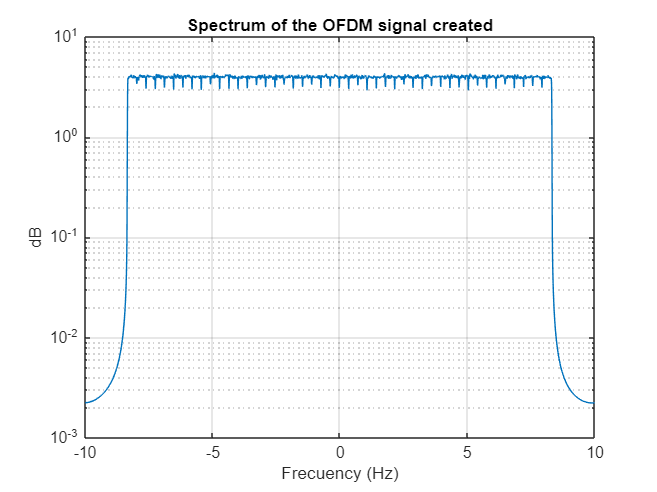

[p,f] = pspectrum(signal);
new_f=f./pi*Fs/2;
semilogy(new_f,fftshift(p))
grid on
title('Spectrum of the OFDM signal created')
xlabel("Frecuency (Hz)")
ylabel('dB')

To finish this section, we can dive deeper into the spectrum represented above. If we analyze it, it is clear that we have 20 MHz of total bandwidth, which is consistent with the fact that our inital sampling frequency, and therefore bandwidth, was *Fs= 20 MHz*. But, if we look at the used bandwidth in the graph, we can see how it comprends the range from -8.3 MHz to 8.3 MHz, which means that the used bandwidth we have obtained is aproximately 16.6 MHz. So let's see if this is what we were expecting from the theoretical formula, that says:

Bandwidth of 1 subcarrier: $\Delta f=\frac{\textrm{Fs}}{N_{\textrm{OFDM}} }=\frac{20\;\textrm{MHz}}{2048}=9\ldotp 765\;\textrm{MHz}$.

Used bandwidth (without guard bands): $\textrm{BW}=\textrm{Fs}-\left(171+172\right)\times \Delta f=16\ldotp 65\;\textrm{MHz}\ldotp$

Therefore, it is clear that the result we have obtained from the simulation is aproximately equal to the one we were expecting theoretically.

In the spectrum of the last section, we can't see the effect of the pilots, since their amplitud is very small (1). In order to evaluate this effect, let's repeat the previous code, but in this case, instead of normalizing the pilots amplitude to *P_ampl=1, *we are setting a value of 10. Due to the fact that this value is considerably bigger than the rest of the data signal, in the spectrum graph below, we can see that instead of getting a flat spectrum in the pass band like before, we are getting many peaks or deltas, that correspond to the different pilots we are introducing in the signal. 

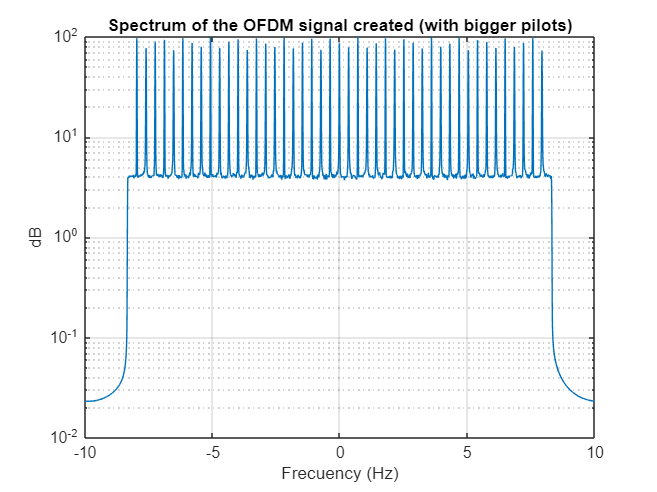

for (symb=1:N_symb)   

    i=sign(rand(1,N_OFDM_ef+num_pilots)-0.5);
    q=sign(rand(1,N_OFDM_ef+num_pilots)-0.5);
    qpsk=i+j*q;

    for index_p=1:num_pilots  
        qpsk(P(index_p)+1)=10; %We fix a higher value for the pilots 
    end
    
    qpsk_ini=zeros(1,N_OFDM);
    qpsk_ini(fg_1+1:N_OFDM-fg_2)=qpsk;

    ofdm=N_OFDM.*ifft(qpsk_ini,N_OFDM);
    ofdm=[ofdm(N_OFDM-Ng+1:N_OFDM),ofdm];

    signal(1,(symb-1)*(N_OFDM+Ng)+1:symb*(N_OFDM+Ng))=ofdm;


end 

[p,f] = pspectrum(signal);
new_f=f./pi*Fs/2;
semilogy(new_f,fftshift(p))
grid on
title('Spectrum of the OFDM signal created (with bigger pilots)')
xlabel("Frecuency (Hz)")
ylabel('dB')

Another interesenting analysis is to represent the OFDM signal we have created in time domain. This way, we'll see the different OFDM symbols in time, one after the other.

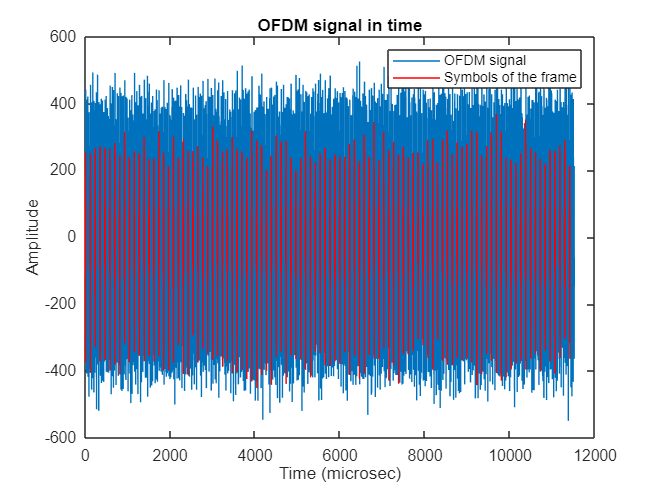

figure
time=(0:1/Fs:((N_symb)*(N_OFDM+Ng))/Fs-1/Fs); 
plot(time,real(signal))
hold on
for (symb=1:N_symb)   
    plot( time( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ),real( signal( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ) ),'r')
end
xlabel('Time (microsec)')
ylabel('Amplitude')
title('OFDM signal in time')
legend('OFDM signal','Symbols of the frame')

In the graph above, we are seeing the complete OFDM signal in time with all its symbols. Moreover, in red, we are remarking each of the 100 symbols (*N_symbols*) that we have sent through the simulation. But, since we are representing many symbols, it's difficult to do a deeper analysis, that's why we are going to continue representing just one OFDM symbol in time. 

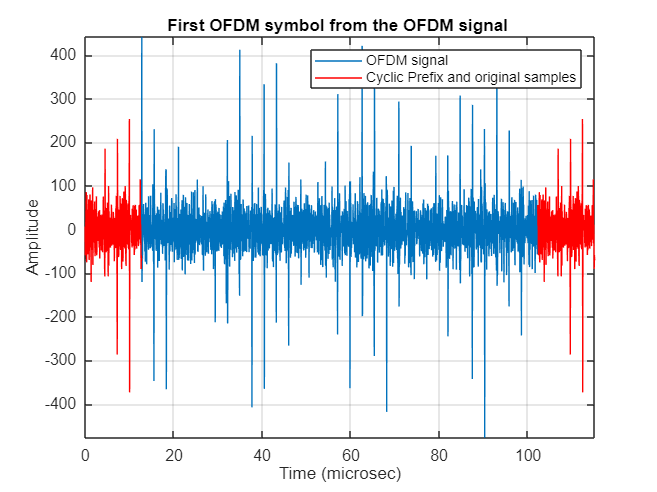

N_symb_represent=1;
figure
time=(0:1/Fs:((N_symb_represent)*(N_OFDM+Ng))/Fs-1/Fs); 
figure
plot(time,real(signal(1:Ng+N_OFDM)))
hold on
for (symb=1:N_symb_represent)   
    plot( time( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ),real( signal( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ) ),'r')
    plot( time(N_OFDM-1:N_OFDM+Ng),real( signal(N_OFDM-1:N_OFDM+Ng) ),'r')
   
end
grid on
xlabel('Time (microsec)')
ylabel('Amplitude')
title('First OFDM symbol from the OFDM signal ')
legend('OFDM signal','Cyclic Prefix and original samples')
axis tight;

In the graph above, we can see at the begining of the signal, in red, the cylic prefix, that as we have explained before, should have 256 samples. Moreover, the cyclic prefix corresponds to the last 256 samples of the original OFDM signal, that have been moved to the initital part of our new signal, this is why the first 256 samples in red (cyclic prefix) are exactly equal to the last 256 samples (also remarked in red). 

In order to verify that the number of samples of the prefix is 256, let's make the same representation as before, but in this case, with the 'x' axis in samples instead of time. 

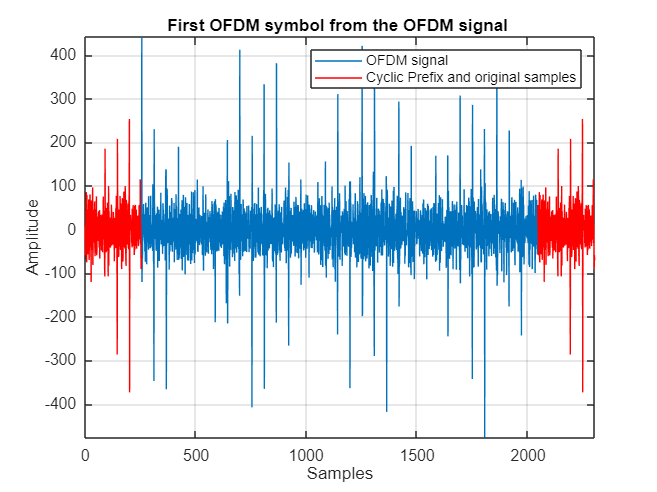

N_symb_represent=1;
figure
samples=(0:1:((N_symb_represent)*(N_OFDM+Ng-1))); 
figure
plot(samples,real(signal(1:Ng+N_OFDM)))
axis tight
%ylim([-150 150])
hold on
for (symb=1:N_symb_represent)   
    plot(samples( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ),real( signal( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ) ),'r')
    plot(samples(N_OFDM-1:N_OFDM+Ng),real( signal(N_OFDM-1:N_OFDM+Ng) ),'r')
   
end
grid on
xlabel('Samples')
ylabel('Amplitude')
title('First OFDM symbol from the OFDM signal ')
legend('OFDM signal','Cyclic Prefix and original samples')

Analyzing the graph above, we can see how the cyclic prefix has 256 samples, that are exactly equal to the last ones, like we were expecting. This means that our OFDM signal implementation is correct. 